close all;
load


Loading from: D:\Users\david\Documents\Cal\model\model-recon-main\matlab.mat



reframe model data

n_model = reframe2(model);

here!


rn_model = reframe3( n_model );

here!


reframe observation data

rn_obs = reframe3( norm_obs )

here!


rn_obs =     0.0947    0.2008    0.1642    0.1458    0.1101    0.1168    0.1637    0.1778    0.1452    0.1693    0.1864    0.2009    0.1643    0.1587    0.1426    0.1699    0.1398    0.1336    0.1468    0.1466    0.1472    0.1230    0.1471    0.1277    0.1293    0.1725    0.1408    0.1432    0.1973    0.2037    0.1660    0.1168    0.1608    0.1227    0.1070    0.1626    0.1672    0.1502    0.1318    0.1915    0.1520    0.1954    0.2091    0.2072    0.1763    0.1578    0.1445    0.1658    0.1682    0.1347
    0.0906    0.1943    0.1594    0.1409    0.1066    0.1114    0.1575    0.1703    0.1397    0.1638    0.1804    0.1945    0.1577    0.1493    0.1348    0.1641    0.1344    0.1269    0.1390    0.1407    0.1411    0.1168    0.1411    0.1228    0.1243    0.1652    0.1348    0.1386    0.1900    0.1954    0.1585    0.1111    0.1559    0.1175    0.1028    0.1585    0.1627    0.1454    0.1256    0.1837    0.1456    0.1867    0.2028    0.1972    0.1700    0.1500    0.1378    0.1603    0.1613

PCA

%% 
[kl_coef, kl_scores, kl_lambda] = pca( rn_model, 'centered', false );
o_scores = rn_obs*kl_coef;

%

plot

plot3( kl_scores(:,1), kl_scores(:,2), kl_scores(:,3), '.');
hold; grid;

Current plot held


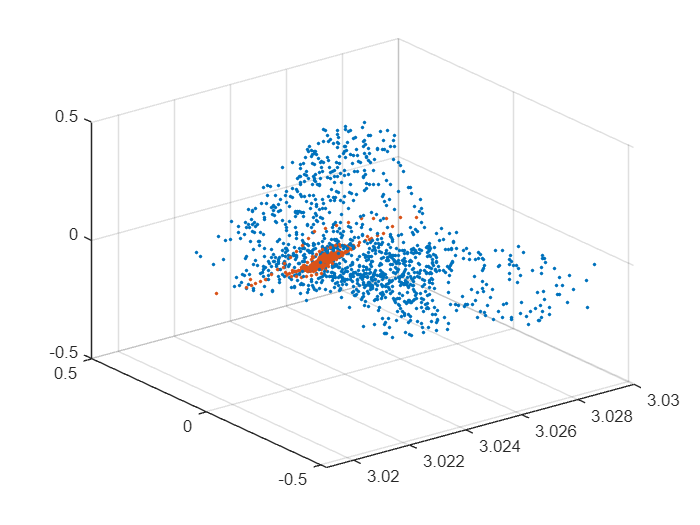

plot3( o_scores(:,1), o_scores(:,2), o_scores(:,3), '.');